disp("Start simulation of model")

Start simulation of model



%Initialise data and filter
load mpu9250new.mat sensorData 
Fs = 10;
acceleration = [sensorData.ax sensorData.ay sensorData.az]

acceleration =          0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100
         0         0    1.0100


gyroscope = [sensorData.gx sensorData.gy sensorData.gz]

gyroscope =     0.0100   -0.0300    0.0200
    0.0400   -0.0100    0.0300
    0.0300    0.0200         0
    0.0300   -0.0300   -0.0100
    0.0300   -0.0400    0.0500
         0         0    0.0200
    0.0400    0.0200    0.0600
         0   -0.0400    0.0200
   -0.0200   -0.0300    0.0300
    0.0100    0.0200    0.0300


magnetometer = [sensorData.mx sensorData.my sensorData.mz]

magnetometer =   -24.5200  -25.4800  -17.5400
  -22.4200  -26.8800  -16.5300
  -24.3400  -27.4000  -17.3700
  -24.1700  -26.1800  -15.8600
  -23.8200  -26.5300  -16.1900
  -25.3900  -26.3600  -16.3600
  -22.2400  -27.7500  -16.7000
  -23.1200  -26.1800  -17.2100
  -24.3400  -27.0500  -17.7100
  -24.8700  -27.9300  -15.8600


decim = 1;
time = (0:decim:size(acceleration,1)-1)/Fs

time =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


fuse = ahrsfilter("SampleRate", 10, "DecimationFactor", decim);
limit = size(time, 2);

%initialise pose plot
pp = poseplot

pp =   PosePatch with properties:

    Orientation: [1×1 quaternion]
       Position: [0 0 0]

  Show all properties


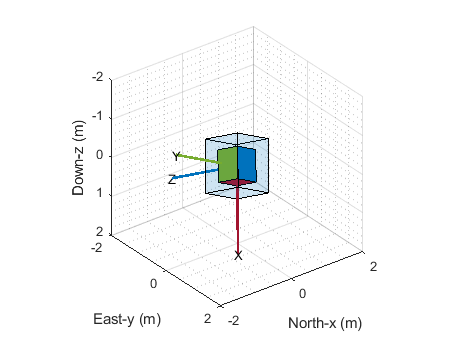

xlabel("North-x (m)")
ylabel("East-y (m)")
zlabel("Down-z (m)");
xlim([-2.00 2.00])
ylim([-2.00 2.00])
zlim([-2.00 2.00])
pos = [0 0 0];

%Create orientation matrix
for i = 1:limit
    q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
    set(pp, Orientation = q, Position = pos);
    drawnow
end


%Start reading values and then fuse them
%c = size(time, 2)
%for i = 1:c
 %   q = fuse(acceleration(i, :), gyroscope(i, :), magnetometer(i, :));
  %  plot(time(i), eulerd(q, "ZYX", "frame"), "MarkerSize", 20);
%end
